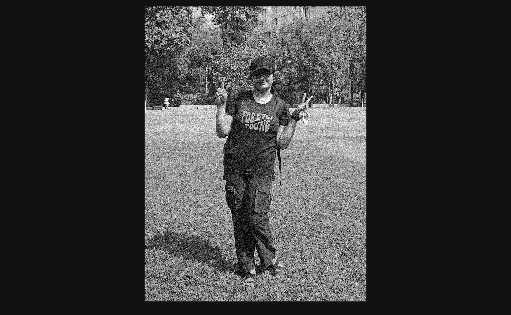

clear all
clc

aa = rgb2gray(imread('DK.jpg'));
a = double(aa);

ab = imnoise(aa,'gaussian'); % adding noise
a = double(ab);

w = [1 1 1 1 1 1 1 1 1] / 9;

[row col] = size(a);

for x = 2:1:row-1
    for y = 2:1:col-1
        
        a1(x,y) = w(1)*a(x-1,y-1) + w(2)*a(x-1,y) + w(3)*a(x-1,y+1) ...
                + w(4)*a(x,y-1)   + w(5)*a(x,y)   + w(6)*a(x,y+1) ...
                + w(7)*a(x+1,y-1) + w(8)*a(x+1,y) + w(9)*a(x+1,y+1);
            
    end
end

figure(1)
imshow(uint8(a))
exportgraphics(gcf, 'M1.png', 'Resolution', 300)

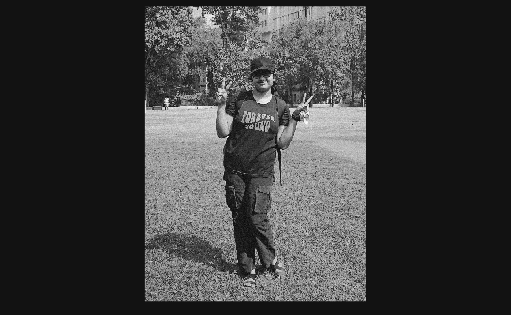


figure(2)
imshow(uint8(a1))
exportgraphics(gcf, 'M2.png', 'Resolution', 300)